# TP.1. SVF Cart Pendulum 

Parameters

m = 0.125; % kg
M = 0.261; % kg
l = 0.337; % m
g = 9.81; % m/s^2

State matrix

A = [0 ((M+m)*g)/(M*l) 0 0;
    1 0 0 0;
    0 -(m*g)/M 0 0;
    0 0 1 0];
B = [-1/(M*l); 0; 1/M; 0];
C = [0 0 0 1];

Controllabliity

con = ctrb(A,B);
rank(con)

ans = 4

ORTF

ORSys = ss(A,B,C,0);
ORTF = tf(ORSys)

ORTF =
 
  3.831 s^2 - 3.403e-15 s - 111.5
  -------------------------------
  s^4 - 1.776e-15 s^3 - 43.05 s^2
 
Continuous-time transfer function.
Model Properties


pole(ORSys)

ans =          0
         0
    6.5613
   -6.5613


zeros = zero(ORSys)

zeros =    -5.3953
    5.3953


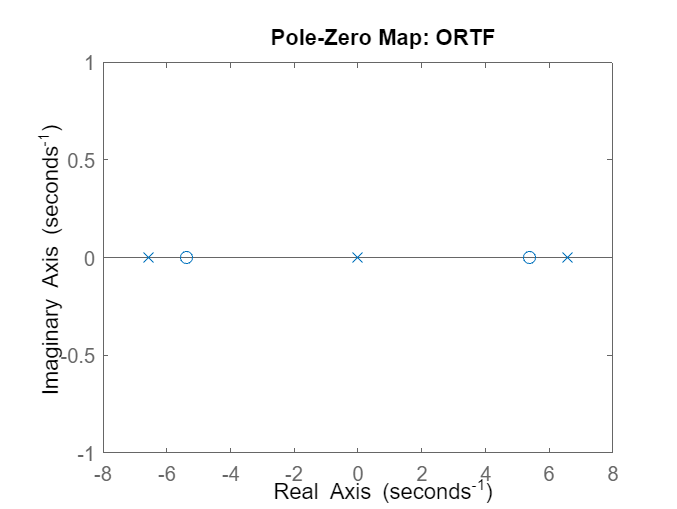

pzmap(ORSys)
title("Pole-Zero Map: ORTF")

DCP Equation

syms s zeta w_n p_1 p_2
DCP = (s^2+2*zeta*w_n*s+w_n^2)*(s+p_1)*(s+p_2)

$$DCP = \left(p_{1}+s\right)\,\left(p_{2}+s\right)\,\left(s^{2}+2\,\zeta \,s\,w_{n}+{w_{n}}^{2}\right)$$

simplifiedExpr = expand(DCP)

$$simplifiedExpr = s^{2}\,{w_{n}}^{2}+p_{1}\,s^{3}+p_{2}\,s^{3}+s^{4}+p_{1}\,p_{2}\,s^{2}+p_{1}\,p_{2}\,{w_{n}}^{2}+p_{1}\,s\,{w_{n}}^{2}+p_{2}\,s\,{w_{n}}^{2}+2\,s^{3}\,w_{n}\,\zeta +2\,p_{1}\,s^{2}\,w_{n}\,\zeta +2\,p_{2}\,s^{2}\,w_{n}\,\zeta +2\,p_{1}\,p_{2}\,s\,w_{n}\,\zeta$$

DCP Calculation

T_s = 2; % s
OS = 4.32; % percent
A_zeta = log(OS/100);
zeta = -A_zeta / sqrt(pi^2 + A_zeta^2);
w_n = 4/(T_s*zeta);
p_1 = -zeros(1)

p_1 = 5.3953

p_2 = w_n

p_2 = 2.8283

d0 = p_1*p_2*w_n^2

d0 = 122.0640

d1 = p_1*w_n^2 + p_2*w_n^2 + 2*p_1*p_2*w_n*zeta

d1 = 126.8206

d2 = w_n^2 + p_1*p_2 + 2*p_1*w_n*zeta + 2*p_2*w_n*zeta

d2 = 56.1533

d3 = 2*w_n*zeta + p_1 + p_2

d3 = 12.2236

DesPoles = roots([1 d3 d2 d1 d0])

DesPoles =   -5.3953 + 0.0000i
  -2.0000 + 1.9998i
  -2.0000 - 1.9998i
  -2.8283 + 0.0000i


Control Omputation

K = acker(A,B,DesPoles)

K =    -1.4584   -9.0946   -1.1371   -1.0944


CG = 1/(C*inv(-A + B*K)*B)

CG = -1.0944

CLTF

CLSys = ss(A-B*K,B,C,0);
pole(CLSys)

ans =   -5.3953 + 0.0000i
  -2.0000 + 1.9998i
  -2.0000 - 1.9998i
  -2.8283 + 0.0000i


zero(CLSys)

ans =    -5.3953
    5.3953


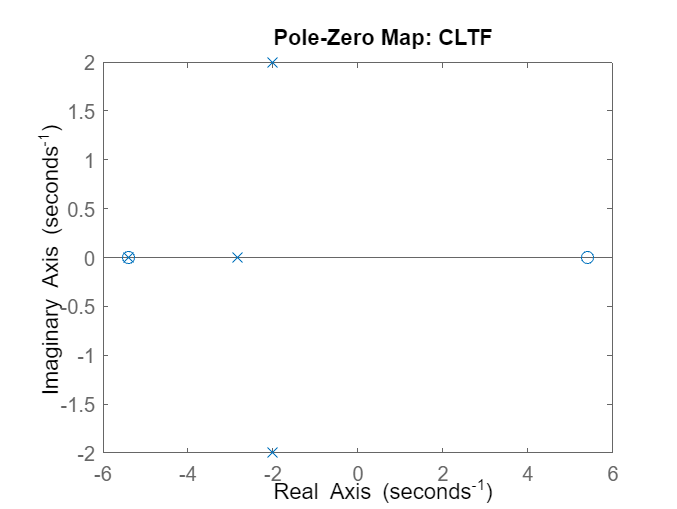

pzmap(CLSys)
title("Pole-Zero Map: CLTF")